# How to call Python from MATLAB

clear
close all

pyenv

ans =   PythonEnvironment with properties:

          Version: "3.11"
       Executable: "/Users/retico/cernbox/Documents/MATLAB/matlab_python/mp_venv/bin/python3.11"
          Library: "/Library/Frameworks/Python.framework/Versions/3.11/lib/libpython3.11.dylib"
             Home: "/Users/retico/cernbox/Documents/MATLAB/matlab_python/mp_venv"
           Status: Loaded
    ExecutionMode: InProcess
        ProcessID: "45917"
      ProcessName: "MATLAB"


pyenv('Version','/Users/retico/cernbox/Documents/MATLAB/matlab_python/mp_venv/bin/python3.11')

ans =   PythonEnvironment with properties:

          Version: "3.11"
       Executable: "/Users/retico/cernbox/Documents/MATLAB/matlab_python/mp_venv/bin/python3.11"
          Library: "/Library/Frameworks/Python.framework/Versions/3.11/lib/libpython3.11.dylib"
             Home: "/Users/retico/cernbox/Documents/MATLAB/matlab_python/mp_venv"
           Status: Loaded
    ExecutionMode: InProcess
        ProcessID: "45917"
      ProcessName: "MATLAB"


py.help('len')

Help on built-in function len in module builtins:

len(obj, /)
    Return the number of items in a container.



py.os.listdir(".")

ans =   Python list with values:

    ['How_to_call_Python_from_MATLAB.mlx', 'some_python_processing.py', 'some_matlab_processing.m', '__pycache__', 'How_to_call_MATLAB_from_Python.ipynb']

    Use string, double or cell function to convert to a MATLAB array.


py.list({'This','is a','list'}) 

ans =   Python list with values:

    ['This', 'is a', 'list']

    Use string, double or cell function to convert to a MATLAB array.


py.math.sqrt(3)

ans = 1.7321

x = rand(2,2);           % MATLAB array
y = py.numpy.array(x);   % numpy array

IM = rand(10)

IM =     0.4709    0.4302    0.6028    0.8010    0.5211    0.9133    0.4942    0.5000    0.8865    0.0424
    0.2305    0.1848    0.7112    0.0292    0.2316    0.7962    0.7791    0.4799    0.0287    0.0714
    0.8443    0.9049    0.2217    0.9289    0.4889    0.0987    0.7150    0.9047    0.4899    0.5216
    0.1948    0.9797    0.1174    0.7303    0.6241    0.2619    0.9037    0.6099    0.1679    0.0967
    0.2259    0.4389    0.2967    0.4886    0.6791    0.3354    0.8909    0.6177    0.9787    0.8181
    0.1707    0.1111    0.3188    0.5785    0.3955    0.6797    0.3342    0.8594    0.7127    0.8175
    0.2277    0.2581    0.4242    0.2373    0.3674    0.1366    0.6987    0.8055    0.5005    0.7224
    0.4357    0.4087    0.5079    0.4588    0.9880    0.7212    0.1978    0.5767    0.4711    0.1499
    0.3111    0.5949    0.0855    0.9631    0.0377    0.1068    0.0305    0.1829    0.0596    0.6596
    0.9234    0.2622    0.2625    0.5468    0.8852    0.6538    0.7441    0.2399    0.

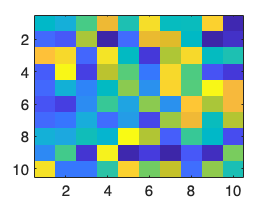

imagesc(IM)

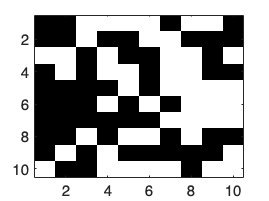

IM_th = IM > 0.5;
imagesc(IM_th); colormap gray

py.importlib.import_module('some_python_processing')

ans =   Python module with properties:

    im_to_mask: [1×1 py.function]
            np: [1×1 py.module]

    <module 'some_python_processing' from '/Users/retico/cernbox/Documents/DIDATTICA/CORSI/AA-2023-2024/CMEPDA/MedPhys-2023-2024/L8_code/matlab_python/some_python_processing.py'>


Im_p = py.numpy.array(IM)

Im_p =   Python ndarray:

    0.4709    0.4302    0.6028    0.8010    0.5211    0.9133    0.4942    0.5000    0.8865    0.0424
    0.2305    0.1848    0.7112    0.0292    0.2316    0.7962    0.7791    0.4799    0.0287    0.0714
    0.8443    0.9049    0.2217    0.9289    0.4889    0.0987    0.7150    0.9047    0.4899    0.5216
    0.1948    0.9797    0.1174    0.7303    0.6241    0.2619    0.9037    0.6099    0.1679    0.0967
    0.2259    0.4389    0.2967    0.4886    0.6791    0.3354    0.8909    0.6177    0.9787    0.8181
    0.1707    0.1111    0.3188    0.5785    0.3955    0.6797    0.3342    0.8594    0.7127    0.8175
    0.2277    0.2581    0.4242    0.2373    0.3674    0.1366    0.6987    0.8055    0.5005    0.7224
    0.4357    0.4087    0.5079    0.4588    0.9880    0.7212    0.1978    0.5767    0.4711    0.1499
    0.3111    0.5949    0.0855    0.9631    0.0377    0.1068    0.0305    0.1829    0.0596   

py.help('some_python_processing')

Help on module some_python_processing:

NAME
    some_python_processing

FUNCTIONS
    im_to_mask(A, th=0.5)
        This function applies the threshold th to convert the A image into a mask

FILE
    /Users/retico/cernbox/Documents/DIDATTICA/CORSI/AA-2023-2024/CMEPDA/MedPhys-2023-2024/L8_code/matlab_python/some_python_processing.py




py.help('some_python_processing.im_to_mask')

Help on function im_to_mask in some_python_processing:

some_python_processing.im_to_mask = im_to_mask(A, th=0.5)
    This function applies the threshold th to convert the A image into a mask



IM_th_py = py.some_python_processing.im_to_mask(Im_p, 0.5) 

IM_th_py =   Python ndarray:

   0   0   1   1   1   1   0   1   1   0
   0   0   1   0   0   1   1   0   0   0
   1   1   0   1   0   0   1   1   0   1
   0   1   0   1   1   0   1   1   0   0
   0   0   0   0   1   0   1   1   1   1
   0   0   0   1   0   1   0   1   1   1
   0   0   0   0   0   0   1   1   1   1
   0   0   1   0   1   1   0   1   0   0
   0   1   0   1   0   0   0   0   0   1
   1   0   0   1   1   1   1   0   1   1

    Use details function to view the properties of the Python object.

    Use logical function to convert to a MATLAB array.


IM_th_mat = logical(IM_th_py);

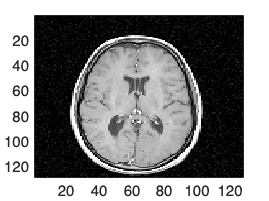

IM= imread("/Users/retico/cernbox/Documents/DIDATTICA/CORSI/AA-2023-2024/CMEPDA/MedPhys/L2_code/MRIslice_noise.png");
imagesc(IM)

IM_p= py.numpy.array(IM);
IM_th_py = py.some_python_processing.im_to_mask(IM_p, 10)

IM_th_py =   Python ndarray:

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

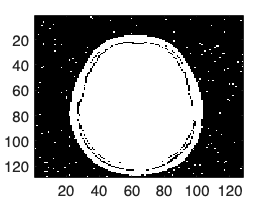

IM_th_mat = logical(IM_th_py);
imagesc(IM_th_mat)